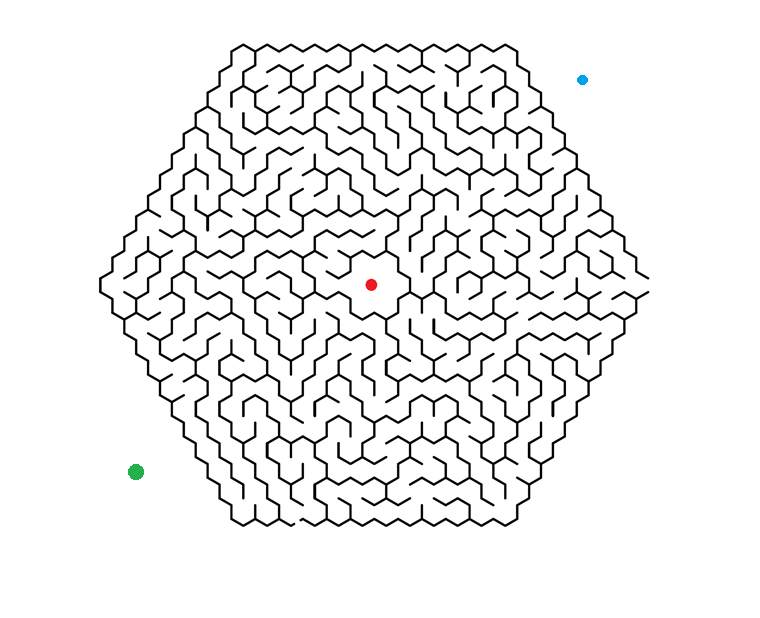

clear all;
close all;
clf;

I = imread('Laberint.png');
I_gray = rgb2gray(I);
imshow(I)

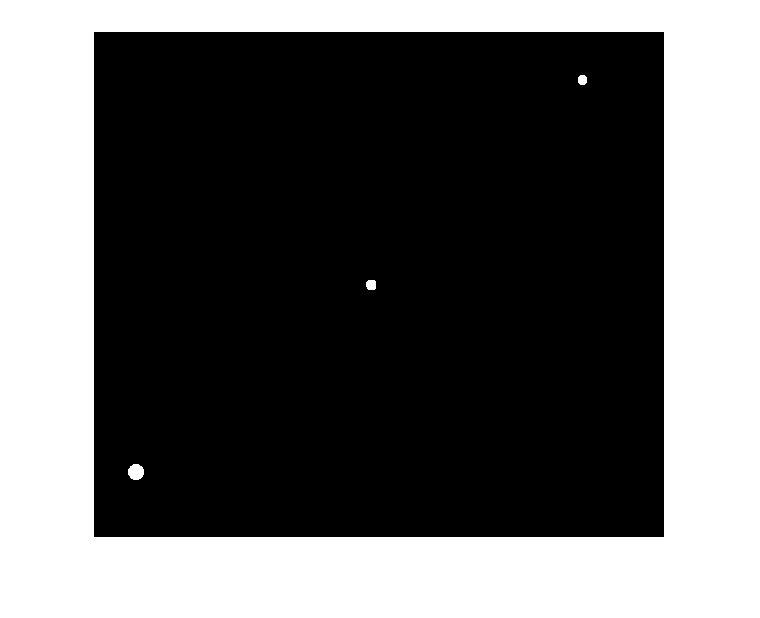


punts = imopen(I_gray < 128, strel('disk',3)); % seleccionem punts exteriors
imshow(punts);

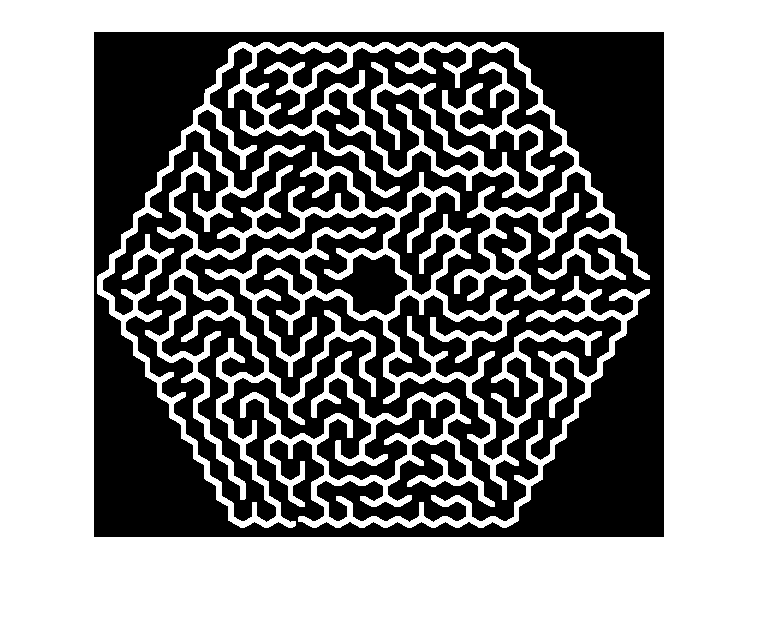

murs = (I_gray < 128) - punts;    % el·liminem els punts exteriors
murs = imerode(murs,ones(2,2));   % refinem el procés anteiror
murs = imdilate(murs, ones(5,5)); % augmentem el gruix dels murs 
imshow(murs)

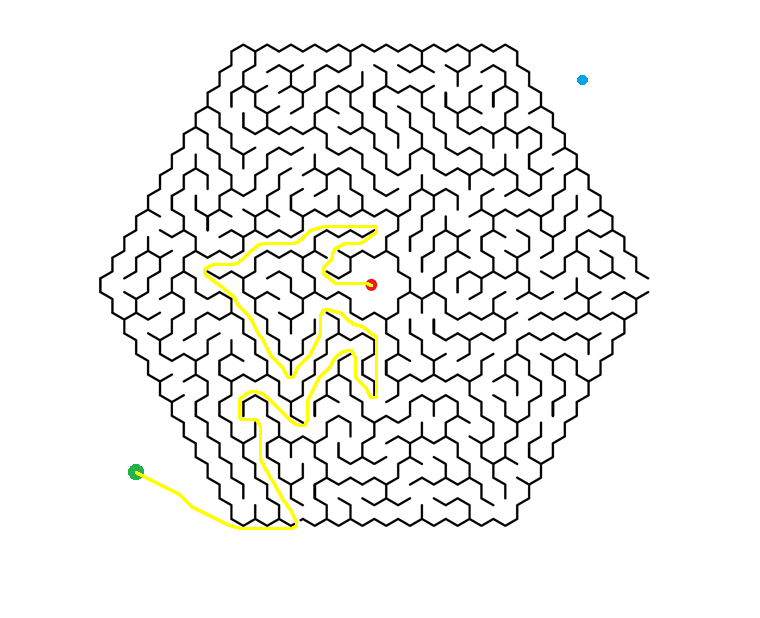


punt_verd = [43 441];
punt_blau = [489 49];
punt_vermell = [278 254];

D_verd = bwdistgeodesic(~murs, punt_verd(1), punt_verd(2), 'quasi-euclidean');
D_blau = bwdistgeodesic(~murs, punt_blau(1), punt_blau(2), 'quasi-euclidean');
D_vermell = bwdistgeodesic(~murs, punt_vermell(1), punt_vermell(2), 'quasi-euclidean');

D_verd_vermell = round(D_verd + D_vermell);
D_blau_vermell = round(D_blau + D_vermell);

D_verd_vermell(isnan(D_verd_vermell)) = inf;
paths_verd_vermell = imregionalmin(D_verd_vermell);
D_blau_vermell(isnan(D_blau_vermell)) = inf;
paths_blau_vermell = imregionalmin(D_blau_vermell);

path_thin_verd_vermell = bwmorph(paths_verd_vermell, 'thin', inf);
path_thin_blau_vermell = bwmorph(paths_blau_vermell, 'thin', inf);

solution_verd_vermell = imdilate(path_thin_verd_vermell, ones(3,3));
solution_blau_vermell = imdilate(path_thin_blau_vermell, ones(3,3));

P_verd = imoverlay(I, solution_verd_vermell, [1 1 0]);
imshow(P_verd)

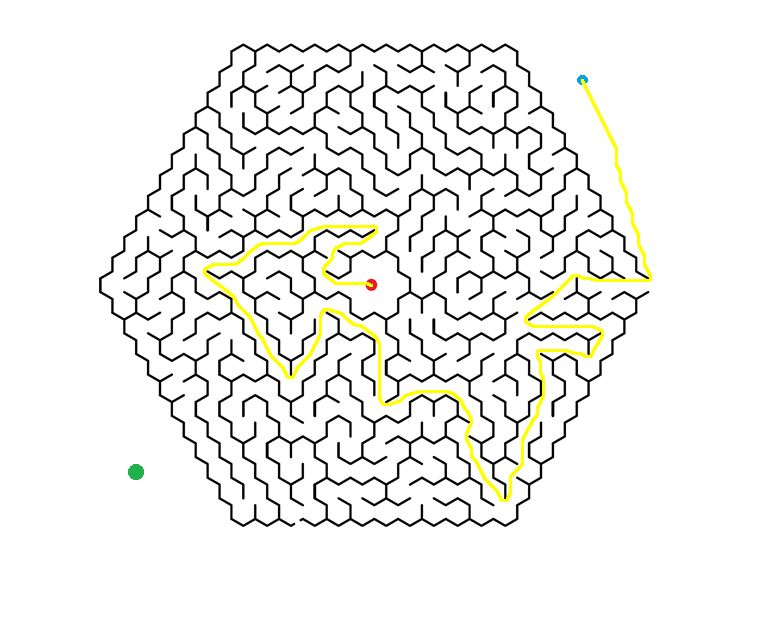

P_blau = imoverlay(I, solution_blau_vermell, [1 1 0]);
imshow(P_blau)


verd_dist = sum(path_thin_verd_vermell(:) == 1)

verd_dist = 1090

blau_dist = sum(path_thin_blau_vermell(:) == 1)

blau_dist = 1410